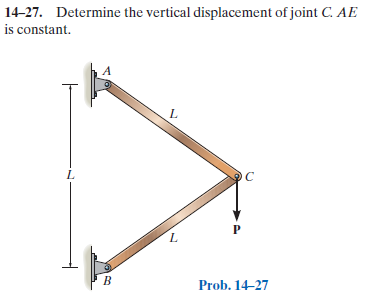

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-27P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-27P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = asind(sym(1/2))*u.deg;
L = sym('L', 'positive');
jointA = [0 0]*L;
jointB = [0 -L];
jointC = L*[cos(theta) -sin(theta)];

# member data

P = sym('P', 'positive');
E = sym('E');
A = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rb', {'Rbx' 'Rby'}, jointB);
t = t.add('concentrated', 'Pc', [0 -P], jointC);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('member', 'Fac', jointA, jointC);
t = t.add('member', 'Fbc', jointB, jointC);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua

$$ua = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0\\ \mathrm{vB} & 0\\ \mathrm{uC} & 0\\ \mathrm{vC} & -\frac{2\,L\,P}{A\,\text{E}} \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fac} & P\\ \mathrm{Fbc} & -P \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & -\frac{\sqrt{3}\,P}{2} & \frac{P}{2} & 0\\ \mathrm{Rb} & \frac{\sqrt{3}\,P}{2} & \frac{P}{2} & 0\\ \mathrm{Pc} & 0 & -P & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fac} & \frac{\sqrt{3}\,P}{2} & -\frac{P}{2} & 0\\ \mathrm{Fbc} & -\frac{\sqrt{3}\,P}{2} & -\frac{P}{2} & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & P\\ \mathrm{Rb} & P\\ \mathrm{Pc} & P \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fac} & 0\\ \mathrm{Fbc} & \frac{\sqrt{3}\,L\,P}{2} \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rb} & 0 & 0 & \frac{\sqrt{3}\,L\,P}{2}\\ \mathrm{Pc} & 0 & 0 & -\frac{\sqrt{3}\,L\,P}{2} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fac} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & -\frac{\sqrt{3}\,L\,P}{2} \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rb} & \frac{\sqrt{3}\,L\,P}{2}\\ \mathrm{Pc} & \frac{\sqrt{3}\,L\,P}{2} \end{array}\right)$$

# clean up

clear ma_f_m ma_f_c la_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
new_assum = assumptions;